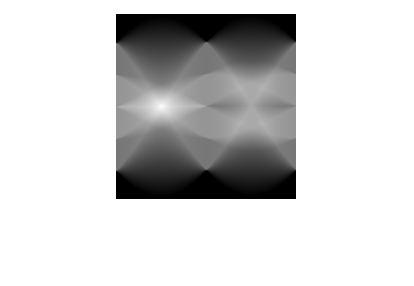

data = load("../materials/projection_data.mat");
proj = data.proj;
[M,N] = size(proj);
r = data.r;
imshow(proj, [])

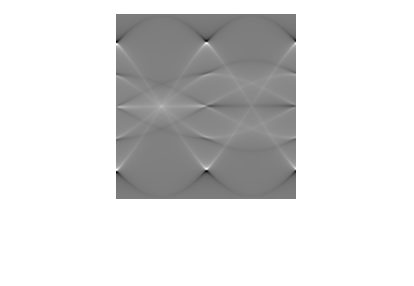

G = fft(proj .* (-1).^(1:M)', [], 1);
window = hann(length(r));
filtered_fft_data =  abs(r)' .* window .* G ; % add hann window to the filter
filtered_data = real(ifft(filtered_fft_data, [], 1) .* (-1).^(1:M)');
imshow(filtered_data, [])

L = floor(M/sqrt(2));
result = zeros([L, L]);
cosine = cosd(0:N-1);
sine = sind(0:N-1);

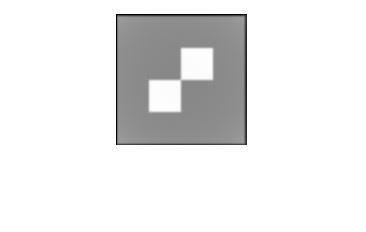

for x=1:L
    for y=1:L
        rhi = (x - L/2)*cosine + (y - L/2)*sine;
        result(x+1,y+1) = sum(interp2(1:N, r, filtered_data, 1:N, rhi));
    end
end
imshow(result,[])